# Dial Detection Trainer

## Combining Ground Truth Objects TestV

% Select Number of GroundTruth Objects to Combine
prompt = {'How Many GroundTruth Objects do you want to create?:'};
dlgtitle = '# of GroundTruths Selector';
dims = [1 20];
definput = {'1'};
answer = inputdlg(prompt,dlgtitle,dims,definput);

gTruths_num = str2double(answer{1});

% Read Data & Combine Ground Truth Objects into an Array

% For each scene . . .
for i = 1:gTruths_num

%     % Select Folder Containing Image Files
%     [im_folder_path] = uigetdir('','Select a Folder Containing Image Files');
%     
%     % Select Blender Export CSV File
%     [blender_csv_name,path_csv] = uigetfile('*.*', "Select a Vertex Data File");
%     path_and_blender_csv_name = strcat(path_csv, blender_csv_name);
%     
%     % Create GroundTruth from Images & Labels (& store in array)
%     gTruth_array(i) = blender_CSV_Image_2_matlab_GroundTruth(im_folder_path, path_and_blender_csv_name);

   % Select Folder Containing Image Files
    [im_folder_path] = uigetdir('','Select a Folder Containing Image Files');
    
    % Select Blender Export CSV File
    [blender_csv_name,path_csv] = uigetfile('*.*', "Select a Vertex Data File");
    path_and_blender_csv_name = strcat(path_csv, blender_csv_name);
    
    % Select Blender SKY BBOXES csv File
    [blender_csv_skyBBOX_name,path_skyBBOX_csv] = uigetfile('*.*', "Select a SKY BBOX Vertex Data File");
    path_and_blender_skyBBOX_csv_name = strcat(path_skyBBOX_csv, blender_csv_skyBBOX_name);
    
    % Create GroundTruth from Images & Labels
    gTruth_array(i) = blender_CSV_Image_2_matlab_GroundTruth_SkyBBOXES(im_folder_path, path_and_blender_csv_name, path_and_blender_skyBBOX_csv_name);


end

% load C:\BU\Semeter_8_(Spring2023)\Deep_Learning_Training\Dial_Reader_TESTS\Photo_Images_Labels.mat
% load C:\BU\Semeter_8_(Spring2023)\Deep_Learning_Training\Real_Dial_Dataset_Stuff\Real_Dial_Dataset_Labels1_fixed.mat
load C:\BU\Semeter_8_(Spring2023)\Deep_Learning_Training\Real_Dial_Dataset_Stuff\Real_Dial_Dataset_Labels2(more).mat
gTruth_array(i+1) = gTruth;

% Create Training Table from Array of GroundTruth Objects

% sampling_factor_array = ones(1, (gTruths_num)); % sample each image for each groundTruth dataset
sampling_factor_array = [5, 1];
train_data = objectDetectorTrainingData(gTruth_array, 'SamplingFactor', sampling_factor_array);

% Shuffle Data
rng(0); % set random seed
shuffledIdx = randperm(height(train_data)); % shuffle indeces
data_t = train_data(shuffledIdx,:); % shuffle the data

% Split Data
num_images = length(data_t.imageFilename);
ind_1 = round(0.8 * num_images);
t_v_split_size = round((num_images - ind_1) / 2);
train_data = data_t(1:ind_1, :);
test_data = data_t(ind_1:(ind_1 + t_v_split_size), :);
valid_data = data_t((ind_1 + t_v_split_size):end, :);

# View Bounding Boxes

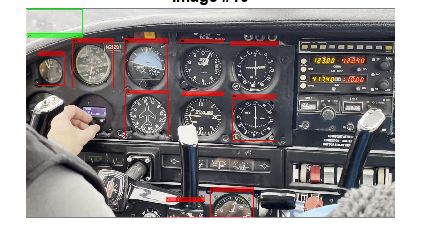

% Choose Image Index
pic_index = 10;

% Read Into Image
im = imread(train_data.imageFilename{pic_index});

annotationLabel = "Dial";
bboxes = train_data.Dial{pic_index};

sky_annotationLabel = "Sky";
sky_bboxes = train_data.Sky{pic_index};

% Create Bounding Box Image
labeledim = insertObjectAnnotation(im, "rectangle", bboxes, annotationLabel, "Color","red", "LineWidth",2);
labeledim = insertObjectAnnotation(labeledim, "rectangle", sky_bboxes, sky_annotationLabel, "Color","green", "LineWidth",2);
% Display
imshow(labeledim)
title(sprintf("Image #%d", pic_index))

# Preprocess Ground Truth

% Create an image datastore
imds = imageDatastore(train_data.imageFilename)

imds =   ImageDatastore with properties:

                       Files: {
                              ' ...\frame2800__spin training -- citabria 7gcaa.mp4_.png';
                              ' ...\Real_Dial_Dataset\frame2850__video from iphone (ground).MOV_.png';
                              ' ...\frame17600__spin training -- citabria 7gcaa.mp4_.png'
                               ... and 142 more
                              }
                     Folders: {
                              ' ...\BU\Semeter_8_(Spring2023)\Deep_Learning_Training\Frames_from_Youtube1';
                              'C:\BU\Semeter_8_(Spring2023)\Deep_Learning_Training\Real_Dial_Dataset';
                              'C:\BU\Semeter_8_(Spring2023)\Blender\Scene2\Frames5_random2'
                              }
    AlternateFileSystemRoots: {}
                    ReadSize: 1
                      Labels: {}
      S

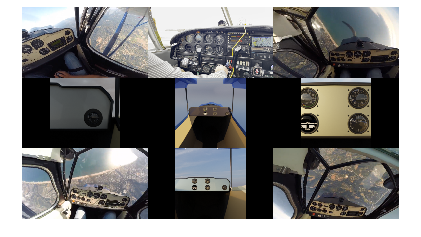


% Look at first 9 images
montage(imds.Files(1:9))



% Create image augmenter
aug = imageDataAugmenter("RandRotation", [-10, 10], "RandXScale", [0.8 1.2], "RandYScale", [0.8 1.2], "RandXReflection",true, "RandXShear",[-5 5], "RandYShear", [-5 5], "FillValue", [0.5,0.5,0.5]);

% Augment image datastore 
augimds = augmentedImageDatastore([224 224 3], imds, "DataAugmentation", aug)

augimds =   augmentedImageDatastore with properties:

             NumObservations: 145
                       Files: {145×1 cell}
    AlternateFileSystemRoots: {}
               MiniBatchSize: 128
            DataAugmentation: [1×1 imageDataAugmenter]
          ColorPreprocessing: 'none'
                  OutputSize: [224 224]
              OutputSizeMode: 'resize'
        DispatchInBackground: 0



% Create a datastore for bounding box label data
bxds = boxLabelDatastore(train_data(:,2:end))

bxds =   boxLabelDatastore with properties:

    LabelData: 
               145x2 cell array
               
               { 6×4 double}    { 6×1 categorical}
               {16×4 double}    {16×1 categorical}
               {11×4 double}    {11×1 categorical}
               
                ... and 142 more rows
    ReadSize: 1



% Combine the datastores (so we can process them both together)
data = combine(imds, bxds)

data =   CombinedDatastore with properties:

      UnderlyingDatastores: {[1×1 matlab.io.datastore.ImageDatastore]  [1×1 boxLabelDatastore]}
    SupportedOutputFormats: ["txt"    "csv"    "xlsx"    "xls"    "parquet"    "parq"    "png"    "jpg"    "jpeg"    "tif"    "tiff"    "wav"    "flac"    "ogg"    "opus"    "mp4"    "m4a"]



% Scale Images & Bounding Boxes Together
scaledData = transform(data,@scaleGT)

scaledData =   TransformedDatastore with properties:

      UnderlyingDatastores: {matlab.io.datastore.CombinedDatastore}
    SupportedOutputFormats: ["txt"    "csv"    "xlsx"    "xls"    "parquet"    "parq"    "png"    "jpg"    "jpeg"    "tif"    "tiff"    "wav"    "flac"    "ogg"    "opus"    "mp4"    "m4a"]
                Transforms: {@scaleGT}
               IncludeInfo: 0



% Preview The Scaled Data (1st image)
newGT = preview(scaledData)

newGT = 1×3 cell array
    {224×224×3 uint8}    {6×4 double}    {6×1 categorical}


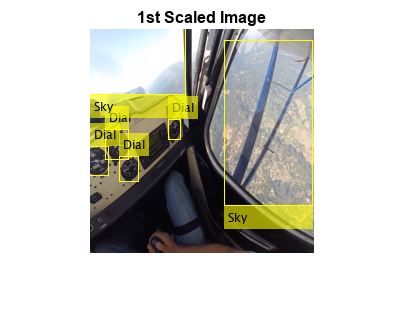


% Look at 1st Image
im = insertObjectAnnotation(newGT{1},"rectangle",newGT{2},newGT{3});
imshow(im)
title("1st Scaled Image")

% CREATE TEST & VALIDATION SCALED DATASTORES

% Create TEST image datastore
test_imds = imageDatastore(test_data.imageFilename)

test_imds =   ImageDatastore with properties:

                       Files: {
                              ' ...\Deep_Learning_Training\Real_Dial_Dataset\frame590__IMG_0268.MOV_.png';
                              ' ...\Blender\Scene2\Frames5_random2\5 Dial_Scene_Random 0001.png';
                              ' ...\frame3200__spin training -- citabria 7gcaa.mp4_.png'
                               ... and 16 more
                              }
                     Folders: {
                              'C:\BU\Semeter_8_(Spring2023)\Deep_Learning_Training\Real_Dial_Dataset';
                              'C:\BU\Semeter_8_(Spring2023)\Blender\Scene2\Frames5_random2';
                              ' ...\BU\Semeter_8_(Spring2023)\Deep_Learning_Training\Frames_from_Youtube1'
                              }
    AlternateFileSystemRoots: {}
                    ReadSize: 1
                      Lab

% Create a datastore for bounding box label data
test_bxds = boxLabelDatastore(test_data(:,2:end))

test_bxds =   boxLabelDatastore with properties:

    LabelData: 
               19x2 cell array
               
               {10×4 double}    {10×1 categorical}
               { 5×4 double}    { 5×1 categorical}
               { 2×4 double}    { 2×1 categorical}
               
                ... and 16 more rows
    ReadSize: 1



% Combine the datastores (so we can process them both together)
data_tst = combine(test_imds, test_bxds)

data_tst =   CombinedDatastore with properties:

      UnderlyingDatastores: {[1×1 matlab.io.datastore.ImageDatastore]  [1×1 boxLabelDatastore]}
    SupportedOutputFormats: ["txt"    "csv"    "xlsx"    "xls"    "parquet"    "parq"    "png"    "jpg"    "jpeg"    "tif"    "tiff"    "wav"    "flac"    "ogg"    "opus"    "mp4"    "m4a"]



% Scale Images & Bounding Boxes Together
scaledData_test = transform(data_tst,@scaleGT)

scaledData_test =   TransformedDatastore with properties:

      UnderlyingDatastores: {matlab.io.datastore.CombinedDatastore}
    SupportedOutputFormats: ["txt"    "csv"    "xlsx"    "xls"    "parquet"    "parq"    "png"    "jpg"    "jpeg"    "tif"    "tiff"    "wav"    "flac"    "ogg"    "opus"    "mp4"    "m4a"]
                Transforms: {@scaleGT}
               IncludeInfo: 0



%--------------------------------------------

% Create VALIDATION image datastore
valid_imds = imageDatastore(valid_data.imageFilename)

valid_imds =   ImageDatastore with properties:

                       Files: {
                              ' ...\Blender\Scene2\Frames5_random2\5 Dial_Scene_Random 0016.png';
                              ' ...\Blender\Scene2\Frames5_random2\5 Dial_Scene_Random 0086.png';
                              ' ...\Deep_Learning_Training\Real_Dial_Dataset\frame1300__IMG_0268.MOV_.png'
                               ... and 16 more
                              }
                     Folders: {
                              'C:\BU\Semeter_8_(Spring2023)\Blender\Scene2\Frames5_random2';
                              'C:\BU\Semeter_8_(Spring2023)\Deep_Learning_Training\Real_Dial_Dataset';
                              ' ...\BU\Semeter_8_(Spring2023)\Deep_Learning_Training\Frames_from_Youtube1'
                              }
    AlternateFileSystemRoots: {}
                    ReadSize: 1
               

% Create a datastore for bounding box label data
valid_bxds = boxLabelDatastore(valid_data(:,2:end))

valid_bxds =   boxLabelDatastore with properties:

    LabelData: 
               19x2 cell array
               
               {4×4 double}    {4×1 categorical}
               {3×4 double}    {3×1 categorical}
               {9×4 double}    {9×1 categorical}
               
                ... and 16 more rows
    ReadSize: 1



% Combine the datastores (so we can process them both together)
data_vld = combine(valid_imds, valid_bxds)

data_vld =   CombinedDatastore with properties:

      UnderlyingDatastores: {[1×1 matlab.io.datastore.ImageDatastore]  [1×1 boxLabelDatastore]}
    SupportedOutputFormats: ["txt"    "csv"    "xlsx"    "xls"    "parquet"    "parq"    "png"    "jpg"    "jpeg"    "tif"    "tiff"    "wav"    "flac"    "ogg"    "opus"    "mp4"    "m4a"]



% Scale Images & Bounding Boxes Together
scaledData_valid = transform(data_vld,@scaleGT)

scaledData_valid =   TransformedDatastore with properties:

      UnderlyingDatastores: {matlab.io.datastore.CombinedDatastore}
    SupportedOutputFormats: ["txt"    "csv"    "xlsx"    "xls"    "parquet"    "parq"    "png"    "jpg"    "jpeg"    "tif"    "tiff"    "wav"    "flac"    "ogg"    "opus"    "mp4"    "m4a"]
                Transforms: {@scaleGT}
               IncludeInfo: 0


# Setup YOLO Anchor Boxes and Architecture

% % Create some inputs for the YOLO architecture
% net = resnet18
% % net = darknet53
% % numClasses = 3;
% % numClasses = 1;
% numClasses = 2;
% imageSize = [224 224 3];
% 
% % Find suitable anchor boxes for the dataset
% anchorBoxes = estimateAnchorBoxes(scaledData,numClasses)
% 
% 
% % Create YOLO v2 architecture
% lgraph = yolov2Layers(imageSize,numClasses,anchorBoxes,net,...
%     "res5b_relu","ReorgLayerSource","res3a_relu")
% % lgraph = yolov2Layers(imageSize,numClasses,anchorBoxes,net,...
% %     "res23","ReorgLayerSource","leakyrelu10")

# Object Detection

% Instructions are in the task pane to the left. Complete and submit each task one at a time.
% 
% This code loads the previously trained network and the test images.
% load pathToImages
% testImds = imageDatastore(pathToImages);
% montage(testImds)

% options = trainingOptions("sgdm", ...
%     "Plots", "training-progress", ...
%     "MaxEpochs", 130, ...
%     "InitialLearnRate",0.001, ...
%     "MiniBatchSize", 64, ...
%     "Shuffle", "every-epoch", ...
%     'CheckpointPath', 'C:\BU\Semeter_8_(Spring2023)\Deep_Learning_Training\Dial_CNN_Training_Checkpoints', ...
%     'ValidationData', scaledData_valid, ...
%     'ValidationFrequency', 30, ...
%     'LearnRateSchedule', 'piecewise', ...
%     'LearnRateDropPeriod', 20);
% 
% detector = trainYOLOv2ObjectDetector(scaledData, lgraph, options)
% % detector = trainYOLOv2ObjectDetector(trainingData,layerGraph,options)

load detector.mat

% Evaluate Results
detectionResults = detect(detector, scaledData_test);

Error using matlab.io.datastore.TransformedDatastore/read
Invalid transform function defined on datastore.

Error in vision.internal.cnn.validation.checkDetectionInputDatastore>iReadNonEmpty (line 73)
        data = read(cpy);

Error in 


% % Evaluate the object detector using average precision metric.
% [ap,recall,precision] = evaluateDetectionPrecision(detectionResults, scaledData_test);
% 
% plot(recall{1},precision{1})
% xlabel('Recall')
% ylabel('Precision')
% grid on
% title(sprintf('DIAL: Average Precision = %.2f',ap))
% 
% plot(recall{2},precision{2})
% xlabel('Recall')
% ylabel('Precision')
% grid on
% title(sprintf('SKY: Average Precision = %.2f',ap))


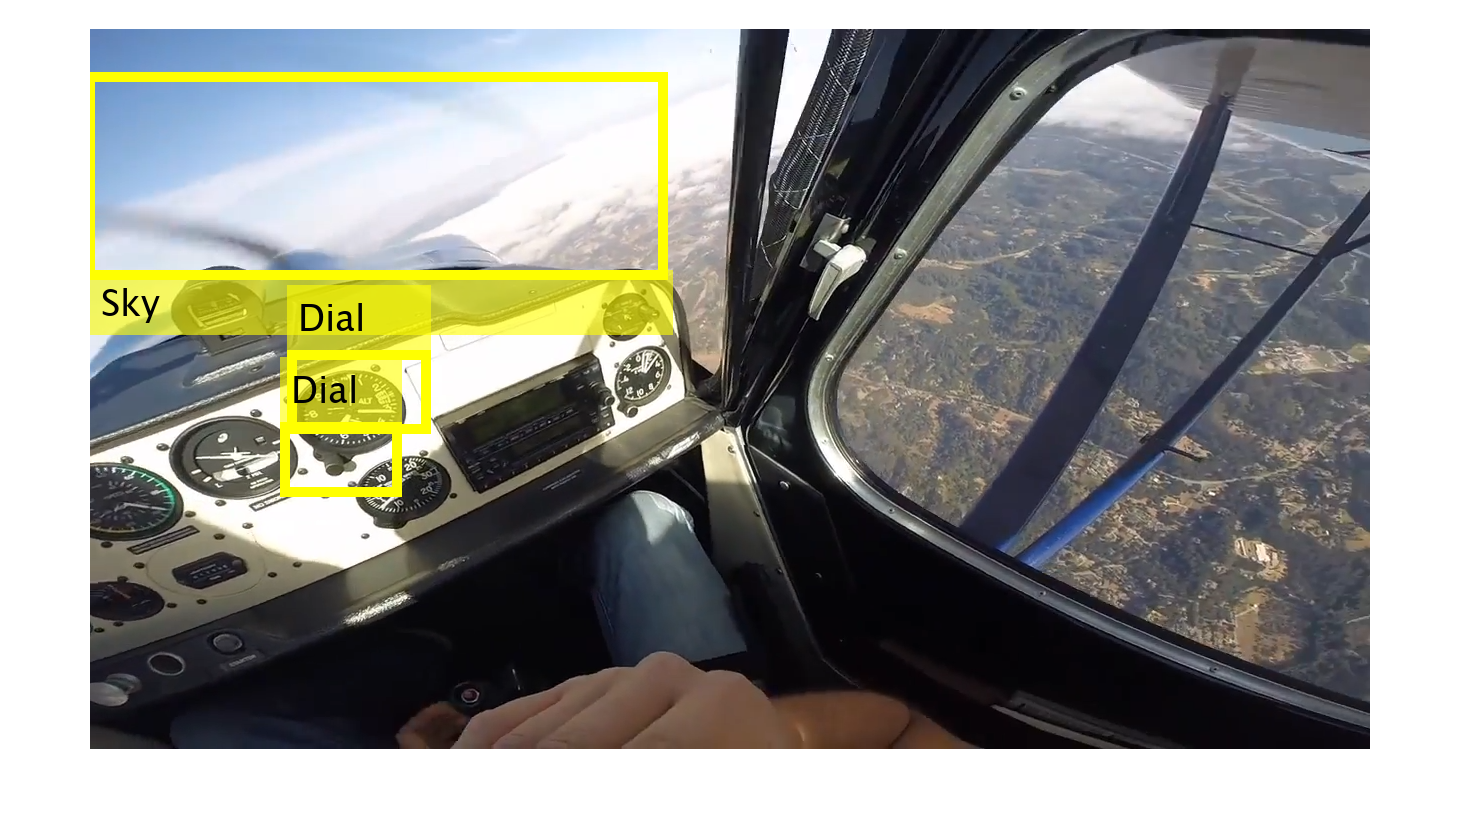

for test_i = 1:length(test_data.imageFilename)
    [test_im_name_path] = test_data.imageFilename{test_i};
    test_im = imread(test_im_name_path);
    
    % This code uses detector to detect dials
    [box,scores,label] = detect(detector,test_im);

    % Annotate the Image 
    test_im_detected = insertObjectAnnotation(test_im, "rectangle", box, label, "LineWidth",10, 'FontSize', 36);
    imshow(test_im_detected)
    title(sprintf("Test Image #%d", test_i))
    scores;
end

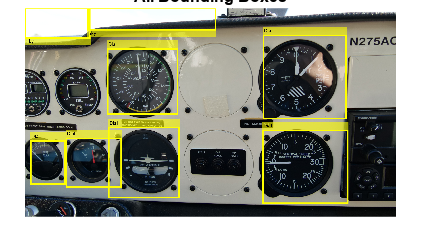

% Read image
% testim1 = imread("Images_from_Videos\frame220__IMG_0268.MOV_.png");
% testim1 = imread("Photo_Images\Visit_10-17-2022 (4).JPG");
% testim1 = imread("C:\BU\Semeter_8_(Spring2023)\Blender\Scene2\Frames2_notNoisey\2 Dial_Scene (100).png");
% testim1 = imread("C:\BU\Semeter_8_(Spring2023)\Blender\Scene2\Frames2_notNoisey\2 Dial_Scene (23).png");
[test_im, test_im_path] = uigetfile("*.*", "Select an Image to Detect");
testim1 = imread(strcat(test_im_path, test_im));

% This code uses detector to detect dials
[box1,score1,label1] = detect(detector,testim1);

% Annotate the Image 
detectedDials = insertObjectAnnotation(testim1, "rectangle", box1, label1, "LineWidth",15, 'FontSize', 48);
imshow(detectedDials)
title("All Bounding Boxes")

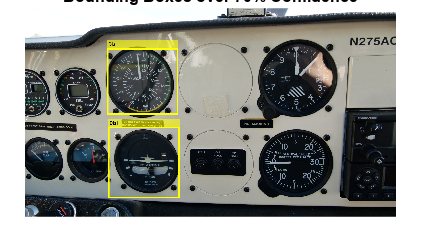


% get indeces of confident bounding boxes
idx = score1 > 0.7; 

% Get the Most confident bounding box
boxTop1 = box1(idx,:);

labelTop1 = label1(idx,:);

detectedDial2 = insertObjectAnnotation(testim1, "rectangle", boxTop1, labelTop1, "LineWidth",15, 'FontSize', 48);
imshow(detectedDial2)
title("Bounding Boxes over 70% Confidence")



% Task 3
% catim = readimage(testImds, 2);
% 
% 
% This code uses rcnn to detect pet faces in catim.
% [cbox,cscore,clabel] = detect(detector,catim)
% load catResults cbox cscore clabel
% cbox
% cscore
% clabel
% 
% Task 4
% % get indeces of confident bounding boxes
% idx = cscore > 0.7; 
% 
% 
% Task 5
% % Get the Most confident bounding box
% cboxTop = cbox(idx,:)
% 
% 
% Task 6
% clabelTop = clabel(idx,:)
% 
% 
% Task 7
% detectedCat = insertObjectAnnotation(catim, "rectangle", cboxTop, clabelTop);
% imshow(detectedCat)

Function to Scale The Ground Truth to the target image size

function data = scaleGT(data)  
    targetSize = [224 224];
    % data{1} is the image
    scale = targetSize./size(data{1},[1 2]);
    data{1} = imresize(data{1},targetSize);
    % data{2} is the bounding box
    data{2} = bboxresize(data{2},scale);
end

Function to Convert Bounding Boxes into Matrix for Display

function bbox_mat = bbox2mat(labelz)
    % label = train_table.labels{#}
    box_amt = size(labelz(:), 1);
    bbox_mat = zeros(box_amt, 4);   % preallocate
    for i = 1:box_amt
        bbox_mat(i,:) = labelz(i).Position;
    end
end